# Feature Engineering with Text 

 Shakespeare’s sonnets have been read and studied for many years. Literary critics group them into two main series: 

- **"Fair Youth" Sonnets # 1-127** **:** The speaker expresses themes like friendship, admiration, and love for a young man. 

- **"Dark Lady" Sonnets # 128-154 :** The speaker and the fair youth have an affair with a woman with dark hair. These address darker themes such as lust, jealousy, and hate. 

Below, you will extract the text of Shakespeare's sonnets, perform preprocessing, and evaluate the predictive power of text features to identify this shift in theme. 

## Reading and Preprocessing

Extract the text of Shakespeare’s sonnets from sonnets.txt using the [`extractFileText`](https://www.mathworks.com/help/textanalytics/ref/extractfiletext.html) function. 

sonnets = extractFileText("sonnets.txt")

To analyze the sonnets in sequence, you'll need to split this single body of text into parts using some structural elements. One way to approach this is to use the Roman numeral heading for each. 

% get the 18th sonnet 
start = " XVIII" + newline;
fin = " XIX";
sonnet18 = extractBetween(sonnets,start,fin)

This is not a bad way to get a single sonnet. This kind of approach could also be applied to extract a chapter from a book or a single section from a research paper using the headings as well. However, it could get tedious if there are many pieces you want to separate all at once. For example, with the sonnets text you would need to do this 154 times. Another approach is to split the text up using spacing between blocks. 

% Split using a double newline since these separate the sonnets
sonnetsChunks = split(sonnets,[newline newline])

Note that this document had consistent formatting which made separating sections relatively easy. In practice, this may not always be the case, and you may need to resort to more complex approaches which combine multiple strategies. 

Looking back at the results, you can see there is some text you'll want to remove. For example, you don't want to analyze the empty spaces, Roman numeral headings, overall title, or author name. Since all these elements seem like they're relatively short compared to sonnets, you can probably use string length to remove them. Double check if there is a clear grouping using a histogram on string lengths. 

% Look at the histogram of string lengths (numer of characters in each) 
sonnetChunkLengths = strlength(sonnetsChunks);
histogram(sonnetChunkLengths,10); 
xlabel("String Length (characters)"); 

Now take a closer look at the sonnets that are above and below 300 characters in length: 

histogram(sonnetChunkLengths(sonnetChunkLengths >= 300)); 
xlabel("String Length (characters)"); 
histogram(sonnetChunkLengths(sonnetChunkLengths < 300 )); 
xlabel("String Length (characters)"); 

It looks like all of the shorter strings are under 25 characters in length. This is too short to be sonnets, since a sonnet is a poetic form with 14 lines and 10 syllables per line, so you can just keep the strings over 300 characters. 

% Get only the sonnets
sonnets = sonnetsChunks(sonnetChunkLengths >= 300)

Now that you have only the sonnets in a string array, you can access any of them using numerical indexing. For example, the 18th sonnet you extracted earlier using Roman numerals and `extractBetween` can be obtained much more easily using 18 as the index into the string array. 

sonnets(18)

## Feature Exploration and Cleaning

Now you're ready to start analyzing the text and engineering features that predict where the “Dark Lady” sonnets begin. The presence and frequency of certain words can classify or predict many things, from whether an e-mail is spam to whether a product review has a positive or negative sentiment. This seems like a promising way to investigate the sonnets for a shift in theme. You’ll need to use the [tokenizedDocument](https://www.mathworks.com/help/textanalytics/ref/tokenizeddocument.html) function to convert each sonnet string into a “document” and it’s unique components or "tokens". In general, tokens can be many things such as words, special characters, punctuation, web addresses, or even emojis. In this case though you just have words and punctuation. 

#### Create a Tokenized Document

tokenizedSonnets = tokenizedDocument(sonnets)

You can visualize the most common tokens ranked using appearance size with the [`wordcloud`](https://www.mathworks.com/help/matlab/ref/wordcloud.html) function. 

wordcloud(tokenizedSonnets);

#### Clean the Tokens

In this case the most common token is a comma. Several of the other most common tokens are also punctuation. You can also see some words are repeated with capitalization differences. Finally many of the words shown are what are called "stop words" such as "but", "by", "for", "am", etc... The `erasePunctuation`, `removeStopWords`, and `lower` functions will address all of these issues. 

tokenizedSonnets = erasePunctuation(tokenizedSonnets); 
tokenizedSonnets = removeStopWords(tokenizedSonnets); 
tokenizedSonnets = lower(tokenizedSonnets); 

While there is no universal definition of stop words, typically they are some of the most common words in a language which provide structure and modify other words but have no independent meaning by themselves. What counts as a stop word can be defined on a case-by-case basis for a given application. You will see an example of doing so later on. To see the default list used in MATLAB use the `stopWords` command as follows. 

words = stopWords;
reshape(words,[25 9])

Take another look at the word cloud. 

wordcloud(tokenizedSonnets); 

All the punctuation, repeated words, and typical stop words are gone, but it looks like some of the remaining words are essentially still stop words, just a Shakespearean variety. This is where defining custom sets of words for removal comes in handy. First define a string array with all of the custom words you want to remove, then provide it to the `removeWords` function as follows. 

shakeStop  = ["thy","thou","thee","thine","doth","hath","nor","dost","hast","art","o"];
tokenizedSonnets = removeWords(tokenizedSonnets,shakeStop); 

wordcloud(tokenizedSonnets);

#### Quantitative Analysis of Tokens

That looks much better. As you might have anticipated if you’re familiar with Shakespeare’s sonnets, it looks like the most common meaningful word is “love”. Word clouds can be useful for getting a quick visual representation of the common elements in a body of text, and doing some initial filtering and cleaning. However, now you'll need to dive deeper into analysis and quantify things like word or phrase appearance numerically. In this case start with the [bagOfWords](https://www.mathworks.com/help/textanalytics/ref/bagofwords.html) function to generate a bag-of-words model (also known as a term-frequency counter), which records the number of times words appear in each document. 

wordBagSonnets = bagOfWords(tokenizedSonnets)

The fields in the output are relatively self explanatory with the exception of the `Counts` matrix. I.e. `Vocabulary` is a list of all the words, `NumWords` is how many words there are, and `NumDocuments` is how many documents there are. `Counts` needs a bit more explanation though.

- Rows in the `Counts` matrix correspond to the tokenized documents 

- Columns correspond to the unique tokens/words. 

- Values in the matrix represent the number of times a particular word (corresponding to the column position) appears in a document (corresponding to the row position). 

% use the full function to visualize the counts matrix since it is returned
% as "sparse" by defualt. 
full( wordBagSonnets.Counts ) 

Note that the order of the words / columns is given in the `Vocabulary` variable, and the order of the documents / rows is preserved from the tokenized document used to create the bag-of-words model. For example, `wordBagSonnets.Counts(153,3042)` is the number of times the word` wordBagSonnets.Vocabulary(3042)` appears in` tokenizedSonnets(153): `

full( wordBagSonnets.Counts(153,3042) )
wordBagSonnets.Vocabulary(3042)
tokenizedSonnets(153)

One way to visualize the structure of the `Counts` matrix is using the `spy` function. Each blue dot represents a nonzero entry. Although you won't see how many times words appear using this visual, you can get a big-picture view of where they do. 

spy(wordBagSonnets.Counts); 
axis normal; 
xlabel("Unique Word #"); 
ylabel("Sonnet"); 

You can sum the columns of the `Counts` matrix to visualize how many times each word appears in all the documents, 

plot(sum(wordBagSonnets.Counts))
xlabel("Unique Word #")
ylabel("Total Appearances")

You can use the `topkwords` function to get a set of the top words sorted by count in a table. 


top10words = topkwords(wordBagSonnets,10)

You can also use the `Vocabulary` variable to extract the column for a particular word to see where it appears and with what frequency. This is a technique you will use later on to extract and evaluate word frequency features to predict the shift in sonnet theme. 

wordToSee = "beauty" ; 
wordPos = wordBagSonnets.Vocabulary == wordToSee; 
bar(wordBagSonnets.Counts(:,wordPos)); % visualize the result with a bar plot 
xlabel("Sonnet"); 
ylabel("Appearances of ''" + wordToSee + "''")

Finally, you can further analyze where and how a word appears using the `context` function. 

wordContext = context(tokenizedSonnets,wordToSee);
disp(wordContext.Context)

## Feature Extraction and Evaluation

To try to find the shift from “Fair Youth” to “Dark Lady” sonnets, you can look for the presence and frequency of “love” versus “hate” over the course of the sonnets. To get at the theme or sentiment associated with these words, you want to account for the various forms they can take such as “loved”, “loves”, or “hated”. 

#### Normalize Words

This can be accomplished by [lemmatizing](https://en.wikipedia.org/wiki/Lemmatisation) or reducing the words to a root form, so for example  "loved" , "loves" , "love" are all reduced to "love". To do this in MATLAB, you can use the [normalizeWords](https://www.mathworks.com/help/textanalytics/ref/normalizewords.html) function as follows: 

First add part-of-speech details to improve the subsequent lemmatization. See [here](https://www.mathworks.com/help/textanalytics/ref/normalizewords.html#mw_71a53b1d-4e5b-4ce2-9118-f3e75fd252b5) for reference. 

tokenizedSonnets = addPartOfSpeechDetails(tokenizedSonnets); 
tokenizedSonnets = normalizeWords(tokenizedSonnets,"Style","Lemma");

#### Re-evaluate Counts 

Now, since you have changed the overall token content, recreate the bag-of-words model.

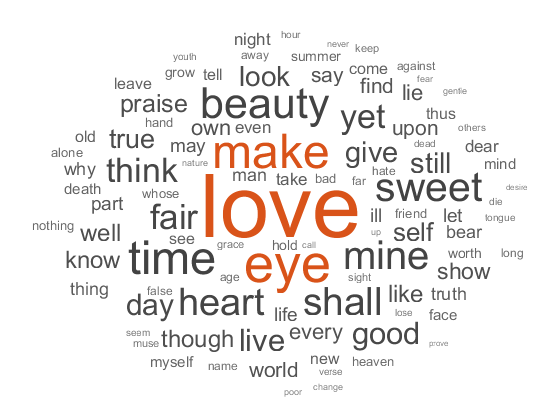

wordBagSonnets = bagOfWords(tokenizedSonnets); 
wordcloud(wordBagSonnets); 

top5words = topkwords(wordBagSonnets)

top5words = 5×2 table
      Word      Count
    ________    _____

    "love"       199 
    "eye"         93 
    "make"        80 
    "time"        78 
    "beauty"      68 


Notice that the specific form “love” appeared 162 times previously (see here), and now that you have normalized other forms you see 199 appearances. Note that if you want to sort all the words with the `topkwords` function you can use the total number of words from the bag-of-words model, i.e. 

sortedWords = topkwords(wordBagSonnets,wordBagSonnets.NumWords)

sortedWords = 2597×2 table
      Word      Count
    ________    _____

    "love"       199 
    "eye"         93 
    "make"        80 
    "time"        78 
    "beauty"      68 
    "sweet"       65 
    "mine"        63 
    "shall"       59 
    "heart"       58 
    "fair"        52 
    "yet"         51 
    "think"       50 
    "live"        45 
    "good"        45 
    "day"         43 
    "give"        42 


You can visualize any subset of the sorted words in order as follows: 

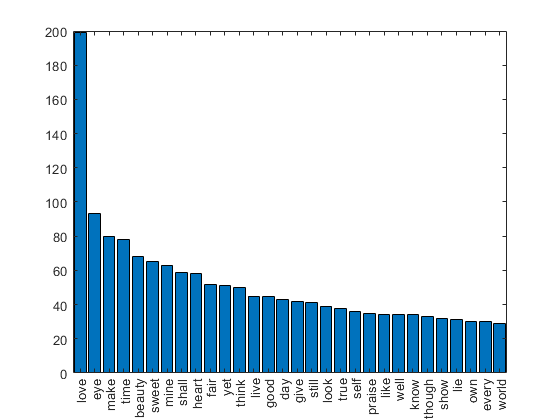

%choose number of words to display
nTop = 30;
% create a categorical variable for display purposes and ensure the sorting
% order is preserved 
topWords = reordercats(categorical(sortedWords.Word(1:nTop)),sortedWords.Word(1:nTop)); 
% extract the corresponding counts 
topCounts = sortedWords.Count(1:nTop); 

%create a bar graph of appearance counts 
bar(topWords,sortedWords.Count(1:nTop))

#### Evaluate Word Frequency Features 

Now take a look at where all the variations of “love” and “hate” are in the sonnets. You can do this as shown previously using the bag-of-words model `Counts` matrix and extracting the columns for "love" and "hate". 

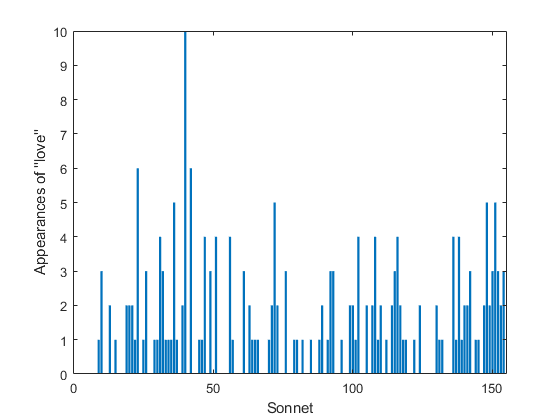

loveLoc = find(wordBagSonnets.Vocabulary == "love"); 
bar(wordBagSonnets.Counts(:,loveLoc)); 
xlabel("Sonnet"); 
ylabel("Appearances of ''love''"); 

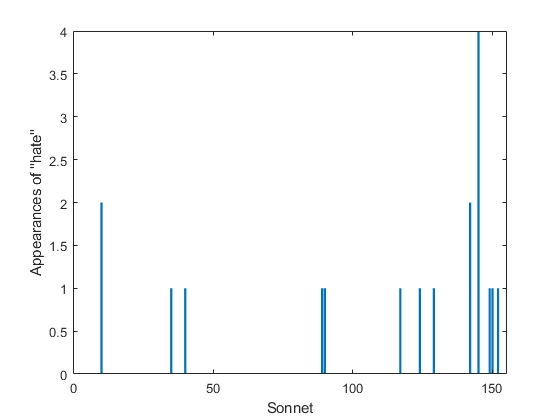

hateLoc = find(wordBagSonnets.Vocabulary == "hate");
bar(wordBagSonnets.Counts(:,hateLoc));  
xlabel("Sonnet"); 
ylabel("Appearances of ''hate''"); 

It looks a bit like love appears throughout the course of the sonnets, and hate appears with a bit more frequency towards the end. However, it’s difficult to really conclude much from just the bar plots. You’ve previously seen how to use summary statistics to extract features for data over time. Since you are interested in the local trends of appearance more than the exact location counts, calculate a normalized moving average of each word’s appearance count. 

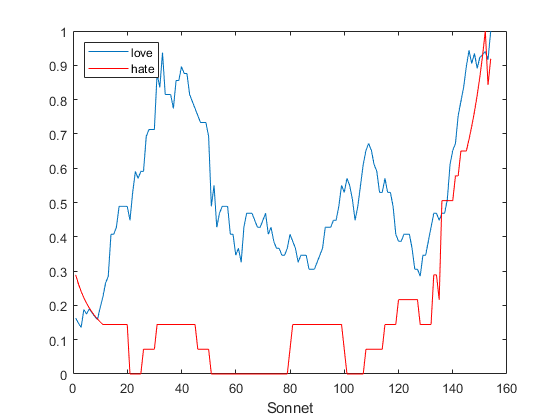

nAve = 20; 
loveDensity = movmean(wordBagSonnets.Counts(:,loveLoc),nAve ); 
hateDensity = movmean(wordBagSonnets.Counts(:,hateLoc),nAve ); 

plot(loveDensity/max(loveDensity))
hold on; 
plot(hateDensity/max(hateDensity),'r'); 
hold off; 

legend(["love","hate"],"Location","northwest")
xlabel("Sonnet"); 

Interestingly, while *love* varies up and down, both *love* and *hate* see a very noticeable increase in appearance at the same time in the later sonnets starting just after number 127. Remember, the "Fair Youth" sonnets end at 127 and the “Dark Lady” sonnets being at 128. Looks like you’ve successfully found this shift in theme using data science! 